# Tutorial: measuring proximity to criticality with $d_2$

## Part 1: application to synthetic data

As a first example, we will calculate $d_2$ for a time series generated by an autoregressive (AR) model:

close all;
kern = [0.8 0.2 -0.1]; sigma = 1; % AR model parameters
T = 1e4; % number of time steps
x = runAR(kern, sigma, T); % simulate AR model

% d2 settings (minimal)
order = 3; % AR model order
deltaT = 1; % time between consecutive steps in time series (in s)
b = 2; % calculate d2 (rather than d4, d6, ...)
with_err_bars = false; % don't calculate error bars
with_QC = false; % don't make quality control plots
with_parallel = false; % don't use parallel computing
fit_method = 'YuleWalker'; % AR fit method

[db, sddb, kern, sigma, H, kernc, exit_status] = calc_db(x, order, deltaT, ...
    b, with_err_bars, with_QC, with_parallel, fit_method);

disp(['best-fit kernel: [' num2str(kern(:)') ']'])

best-fit kernel: [0.78783     0.20972    -0.10539]


disp(['d2 = ' num2str(db) ' bits/s']);

d2 = 0.035026 bits/s


Changing the AR fitting method to maximum likelihood doesn't change the measured d2 value much:

fit_method = 'MaxLikelihood';
[db, sddb, kern, sigma, H, kernc, exit_status] = calc_db(x, order, deltaT, ...
    b, with_err_bars, with_QC, with_parallel, fit_method);
disp(['d2 = ' num2str(db) ' bits/s']);

d2 = 0.035049 bits/s


To double-check that the $d_2$ calculation was successful, we can visually inspect quality control plots:

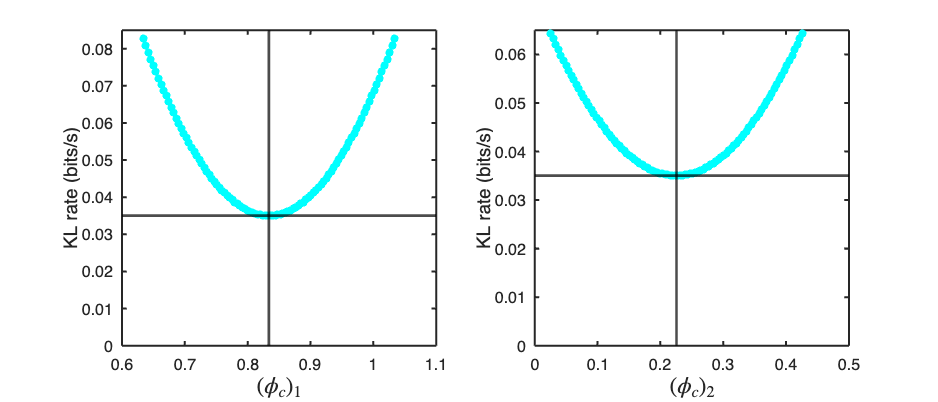

with_QC = true;
[db, sddb, kern, sigma, H, kernc, exit_status] = calc_db(x, order, deltaT, ...
    b, with_err_bars, with_QC, with_parallel, fit_method);
fig = gcf();
fig.Position = [fig.Position(1:2) 700 300];

These plots show how the KL divergence rate from the best-fit AR model to a critical AR model changes as the critical model is varied; each panel corresponds to one component of the critical model's history kernel. The $d_2$ calculation was successful if 

- the numerically calculated minimum in KL rate (where the black lines meet) matches the visual minimum in every panel, and 

- the minimizer hasn't drifted outside of the set of critical AR models (in every panel, the black lines meet at a cyan, rather than red, point)

Next, we will measure the uncertainty in $d_2$ given the observed time series:

with_err_bars = true;
with_QC = false; % turn quality control plots off
[db, sddb, kern, sigma, H, kernc, exit_status] = calc_db(x, order, deltaT, ...
    b, with_err_bars, with_QC, with_parallel, fit_method);

disp(['d2 = ' num2str(db) ' +- ' num2str(sddb) ' bits/s'])

d2 = 0.035049 +- 0.0017057 bits/s


This uncertainty metric is based on how well the observed data constrains the AR fit; if the maximum likelihood AR model is not much more likely (given the observed data) than other AR models (with different values of $d_2$), then the uncertainty in $d_2$ is high.

The duration of the time series, in particular, strongly affects the uncertainty in $d_2$:

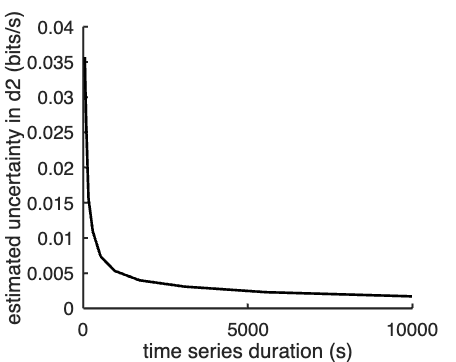

Tlist = round(logspace(log10(50), log10(T), 10)); % time series durations to try
sddb = zeros(size(Tlist));
for Tidx = 1:length(Tlist)
    [db, sddb(Tidx), kern, sigma, H, kernc, exit_status] = calc_db(x(1:Tlist(Tidx)), order, deltaT, ...
        b, with_err_bars, with_QC, with_parallel, fit_method);
end

fig = figure(); plot(Tlist, sddb, 'k', 'LineWidth', 2); 
fig.Position = [fig.Position(1:2) 340 270];
xlabel('time series duration (s)'); ylabel('estimated uncertainty in d2 (bits/s)');
box off; set(gca, 'LineWidth', 1.5); set(gca, 'FontSize', 14)

This makes sense— observing the dynamics for longer makes our measurement of proximity to criticality more reliable.

## Section 2: Application to electrophysiological data

Here we will measure $d_2$ from single-unit extracellular electrophysiological recordings in visual cortex of freely-behaving mice (Senzai et al., Neuron 2019). Along the way, we will highlight some important methodological choices that affect $d_2$.

First, load the data from the demo/ephys_data/ directory (you will have to change the file path to reflect where prox_crit_toolkit is stored on your local machine):

clear;
load('/Users/samsooter/Documents/GitHub/prox_crit_toolkit/demo/ephys_data/YMV15.mat')

The array `st` contains spike times (in units of seconds), `clu` identifies which neurons fired the spikes in `st`; and `WAKE`, `NREM`, and `REM` contain time windows in which the animal was in each of these behavioral states.

To calculate $d_2$, we first need to convert spikes to a time series. The simplest way to do this is to split the session into equally spaced time bins and count the number of spikes in each bin:

deltaT = 0.04; % time bin length (in seconds)
x = get_spike_counts(st, min(st), max(st), deltaT); % make spike-count time series

% d2 settings
order = 5; b = 2; with_err_bars = true; 
with_QC = false; with_parallel = false; fit_method = 'MaxLikelihood';

% calculate d2
[db, sddb, kern, sigma, H, kernc, exit_status] = calc_db(x, order, deltaT, ...
    b, with_err_bars, with_QC, with_parallel, fit_method);

disp(['d2 = ' num2str(db) ' +- ' num2str(sddb) ' bits/s'])

d2 = 1.6872 +- 0.0081069 bits/s


This $d_2$ value was calculated using the entire recording session, including periods of `WAKE`, `NREM`, and `REM` all thrown together. However, the dynamical state of the brain fluctuates dramatically over time, especially as the animal transitions between different behavioral states. We will therefore next calculate $d_2$ separately for `WAKE`, `NREM`, and `REM:`

% curate spike-count time series for each behavioral state
states = {double(WAKE), double(NREM), double(REM)};
labels = {'WAKE', 'NREM', 'REM'};
x = cell(size(states));
for idx = 1:length(states)
    x{idx} = cell(size(states{idx}, 1), 1);
    for w = 1:size(states{idx}, 1)
        x{idx}{w} = get_spike_counts(st, states{idx}(w, 1), states{idx}(w, 2), deltaT);
    end
end

% calculate d2 for each state
for idx = 1:length(states)
    [db, sddb, kern, sigma, H, kernc, exit_status] = calc_db(x{idx}, order, deltaT, ...
        b, with_err_bars, with_QC, with_parallel, fit_method);
    disp(['d2 (' labels{idx} ') = ' num2str(db) ' +- ' num2str(sddb) ' bits/s'])
end

d2 (WAKE) = 0.98413 +- 0.015695 bits/s
d2 (NREM) = 2.5273 +- 0.0149 bits/s
d2 (REM) = 1.4544 +- 0.032053 bits/s


To take this a step further, we can calculate $d_2$ in a short sliding window. To reduce run time, we will turn the `with_err_bars` option off. (However, exploring the tradeoff between the time resolution of $d_2$ and the uncertainty in $d_2$ is a good exercise and is a recommended step when applying $d_2$ to your own data.) This code block usually takes about 5 minutes to run.

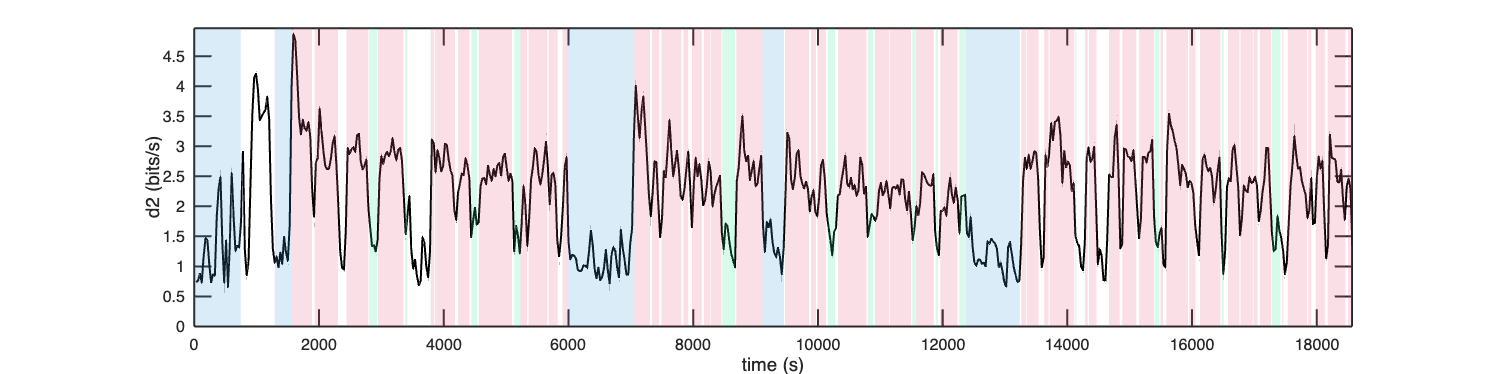

T = 60; % window duration (in s)
slide = 30; % slide between consecutive windows

with_err_bars = false; % to save time, don't calculate error bars

% calculate d2 in sliding window
start = min(st):slide:(max(st)-T);
d2 = zeros(size(start));
for i = 1:length(start)
    x = get_spike_counts(st, start(i), start(i)+T, deltaT);
    [d2(i), sddb, kern, sigma, H, kernc, exit_status] = calc_db(x, order, deltaT, ...
        b, with_err_bars, with_QC, with_parallel, fit_method);
end

% plot results
fig = figure(); hold on;
plot(start+T/2, d2, 'k', 'LineWidth', 1.5);

% annotate by sleep state
colors = [[71, 158, 215] ; [230, 94, 132] ; [52, 235, 149]]/255;
for idx = 1:length(states)
    for w = 1:size(states{idx}, 1)
        t1 = states{idx}(w, 1); t2 = states{idx}(w, 2);
        fill([t1 t2 t2 t1], [0 0 max(d2)+0.1 max(d2)+0.1], colors(idx, :), 'FaceAlpha', 0.2, 'EdgeColor', 'none');
    end
end
set(gca, 'FontSize', 12);
xlabel('time (s)', 'FontSize', 14);
ylabel('d2 (bits/s)', 'FontSize', 14);
fig.Position = [fig.Position(1:2) 1200 300];
ylim([0 max(d2)+0.1]);
xlim([0 max([max(states{1}(:)) max(states{2}(:)) max(states{3}(:))])])
box on;
set(gca, 'LineWidth', 1.5);

We made three key methodological choices to generate this plot:

- the time bin length `deltaT` for converting spikes to a spike-count time series,

- the AR model order `order`, and

- the duration `T` of the sliding window.

There is no one-size-fits-all procedure for selecting the values of these parameters, and in general you should vary them over a broad range to check the robustness of your results. However, here are a few tips to keep in mind:

-  `deltaT` should be at least as long as the mean interspike interval (ISI); otherwise, the spike count time series will consist mostly of 0s and 1s, which isn't good for AR model fitting.

- If the estimated uncertainty in $d_2$ is comparable in size to the actual $d_2$ value, then you should increase `T`.

- `deltaT` and `order` should be held fixed across different experimental conditions (such as sleep vs. wake) for fair comparisons.

- The total temporal reach of the AR model (`deltaT`$\times$`order`) usually matters more for $d_2$ than either `deltaT` or `order` individually. This makes it reasonable to (for example) fix `deltaT` and vary `order` on a first pass through your data. 

- In some simple models where the ground-truth distance to criticality can be calculated and compared to measured $d_2$ values, the agreement is usually best when `deltaT`$\times$`order` matches the built-in interaction timescale of the model (Sooter et al., TBD). This suggests that the choice of `deltaT`$\times$`order` for real neural data could be guided by known biophysical time constants, though nailing down a specific number is challenging in practice.

Auxiliary functions used for this demo:

function x = runAR(kern, sigma, T)
kern = kern(:);
x = zeros(1, T);
for t = 1:T
    hist = fliplr(x(max(1, t-length(kern)):(t-1)));
    x(t) = hist*kern(1:length(hist)) + sigma*randn;
end
end

function x = get_spike_counts(st, t1, t2, deltaT)
    bins = t1:deltaT:t2;
    x = histc(st, bins);
end